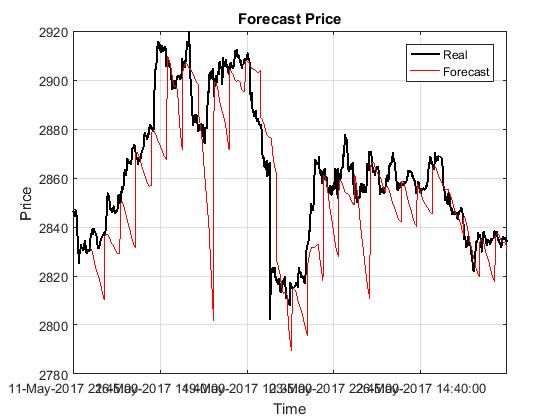

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Loop simulate for long term
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
TN = 1000;
mvN = 15;
%prc = ML_M5.Close(end-TN-mvN+1:end);
prc = (ML_M5.High(1:TN+mvN) + ML_M5.Low(1:TN+mvN))/2;
[~,TSpl] = movavg(prc,7,mvN,'e');
TSpl = TSpl(mvN+1:end);
prc = prc(mvN+1:end);
trN = 12;
ftN = 12;
Y = zeros(TN+ftN,1);
%
mdl = arima('Constant',0,'ARLags',1,'D',1,'Distribution','t');
for i = trN+1:ftN:TN
    winSpl = TSpl(i-trN:i-1);
    est = estimate(mdl,winSpl,'Display','off');
    if winSpl(end) > winSpl(1) + std(winSpl)
        rng('default');
    else
        rng(10,'v5uniform');
    end
    y1 = simulate(est,ftN,'Y0',winSpl,'NumPaths',2);
    Y(i:i+ftN-1) = mean(y1,2);
end
figure;
plot(prc,'k','LineWidth',1.5);
ah = gca;
ah.XLim = [0,TN];
ah.XTick = 1:TN/5:TN;
ah.XTickLabel = datestr(ML_M5.Time(end-TN+1:TN/5:end));
hold on;
plot(trN+1:TN,Y(trN+1:TN),'r');
hold off;
legend('Real','Forecast');
title('Forecast Price');
xlabel('Time');
ylabel('Price');
grid;

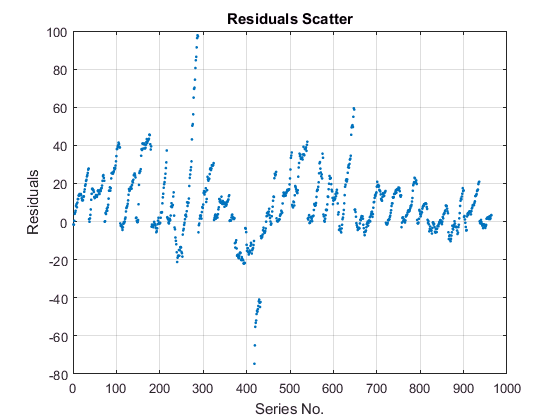

res = prc(trN+1:end) - Y(trN+1:TN);
figure;
plot(res,'.');
grid;
xlabel('Series No.');
ylabel('Residuals');
title('Residuals Scatter');

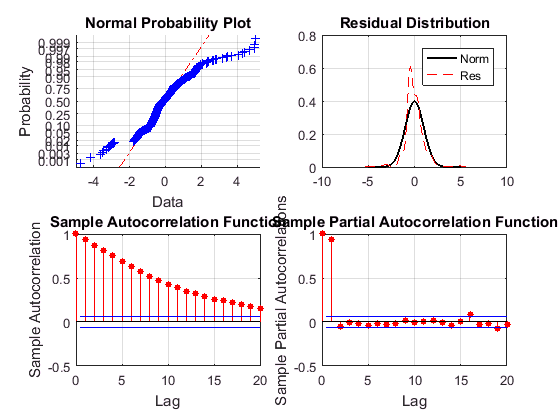

ste = (res - mean(res))./std(res);
[f,xi] = ksdensity(ste);
x = -5:.05:5;
figure;
subplot(2,2,1);
normplot(ste);
subplot(2,2,2);
plot(x,normpdf(x),'k','LineWidth',1.5);
hold on;
plot(xi,f,'r--');
hold off;
grid;
title('Residual Distribution');
legend('Norm','Res');
subplot(2,2,3);
autocorr(ste);
subplot(2,2,4);
parcorr(ste);

lbqtest(res)

ans =    1


archtest(res)

ans =    1


adftest(res)

ans =    1
